## **Linear Algebra Homework 2.**

**윤지상_ 미래자동차공학과 2019092115**

## **Exercise 1. **

### **Write the code that crates figure(Vector sum)**

**1-1. Visualization of v + w Vector**

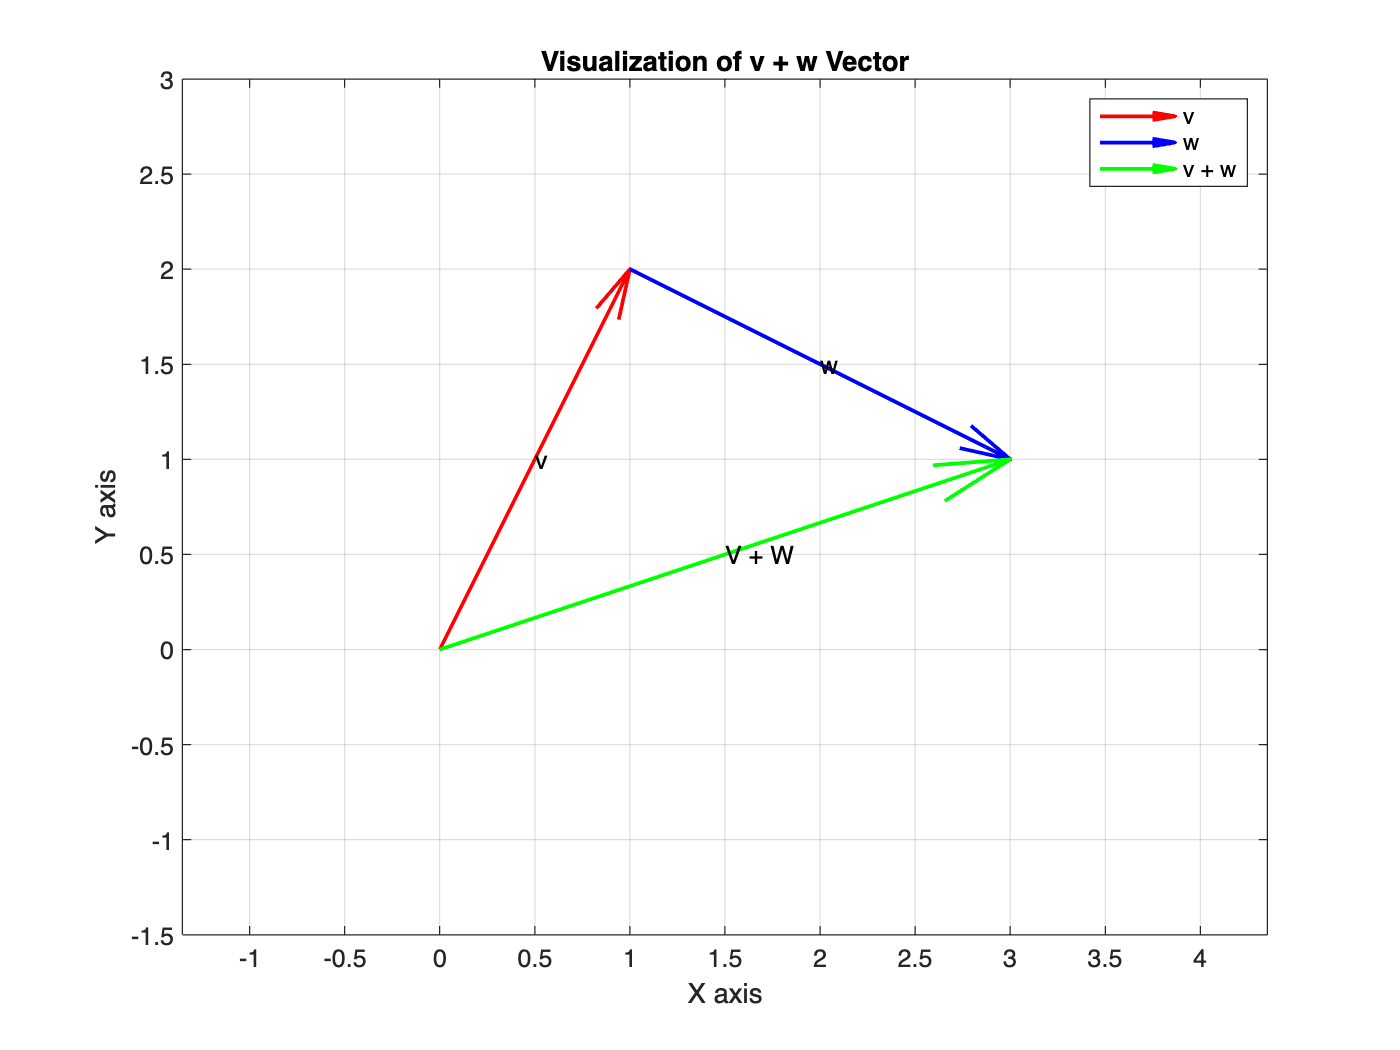

v = [1, 2];
w = [2, -1];
vPlusW = v + w;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v');
hold on;
quiver(v(1), v(2), w(1), w(2), 0, 'b', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='w');
quiver(0, 0, vPlusW(1), vPlusW(2), 0, 'g', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v + w');
hold off;

legend('show');
grid on;

xlabel('X axis');
xlim([-1.5, 4]);
ylabel('Y axis');
ylim([-1.5, 3]);
title('Visualization of v + w Vector');
axis equal;

text(1.5, 0.5, 'V + W');
text(0.5, 1, 'v');
text(2, 1.5, 'w');

**1-2 Visualization of v - w Vector**

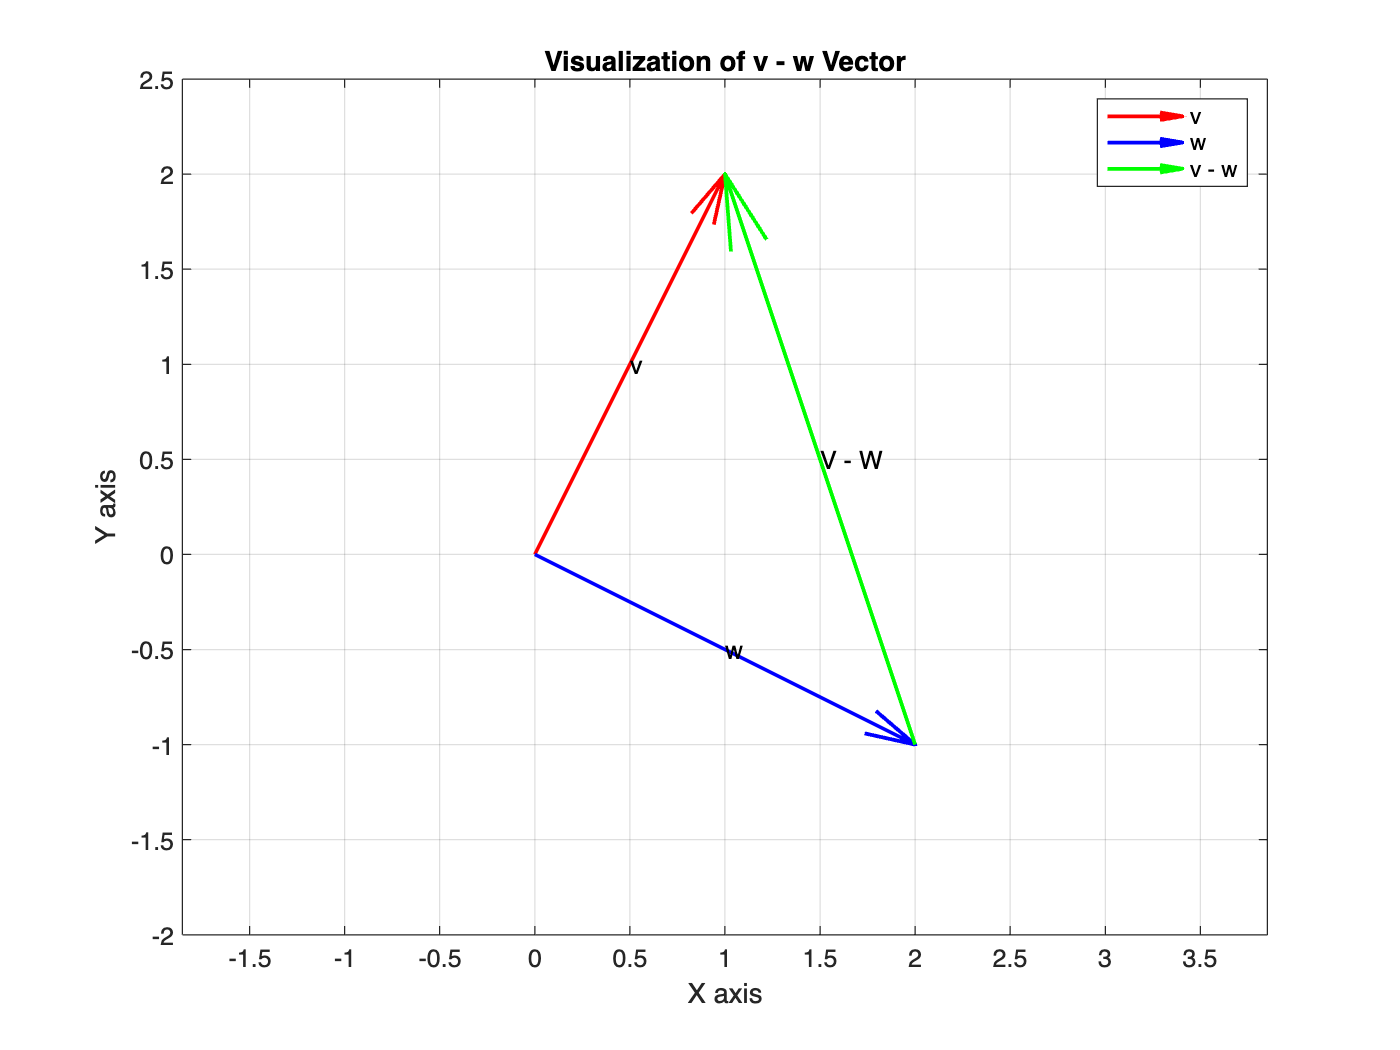

v = [1, 2];
w = [2, -1];
vMinuxW = v - w;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v');
hold on;
quiver(0, 0, w(1), w(2), 0, 'b', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='w');
quiver(w(1), w(2), vMinuxW(1), vMinuxW(2), 0, 'g', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='v - w');
hold off;

legend('show');
grid on;

xlabel('X axis');
xlim([-2, 3]);
ylabel('Y axis');
ylim([-2, 2.5]);
title('Visualization of v - w Vector');
axis equal;

text(1.5, 0.5, 'V - W');
text(0.5, 1, 'v');
text(1, -0.5, 'w');

## Exercise 2. 

### Implement a function that takes a vector as input and outputs a unit vector in the same direction.

clc;
clear;

%v = [2, 3];
v = input('Enter a vector [a b]: ');

function u = unitVec(vec)
    v_L2_norm = norm(vec, 2);
    disp(['Original vector L2 norm: ', num2str(v_L2_norm)]);
    u = vec / v_L2_norm;
end

u_v = unitVec(v); % made unit vector

Original vector L2 norm: 3.7417


disp(['Unit vector L2 norm: ', num2str(norm(u_v, 2))]);

Unit vector L2 norm: 1


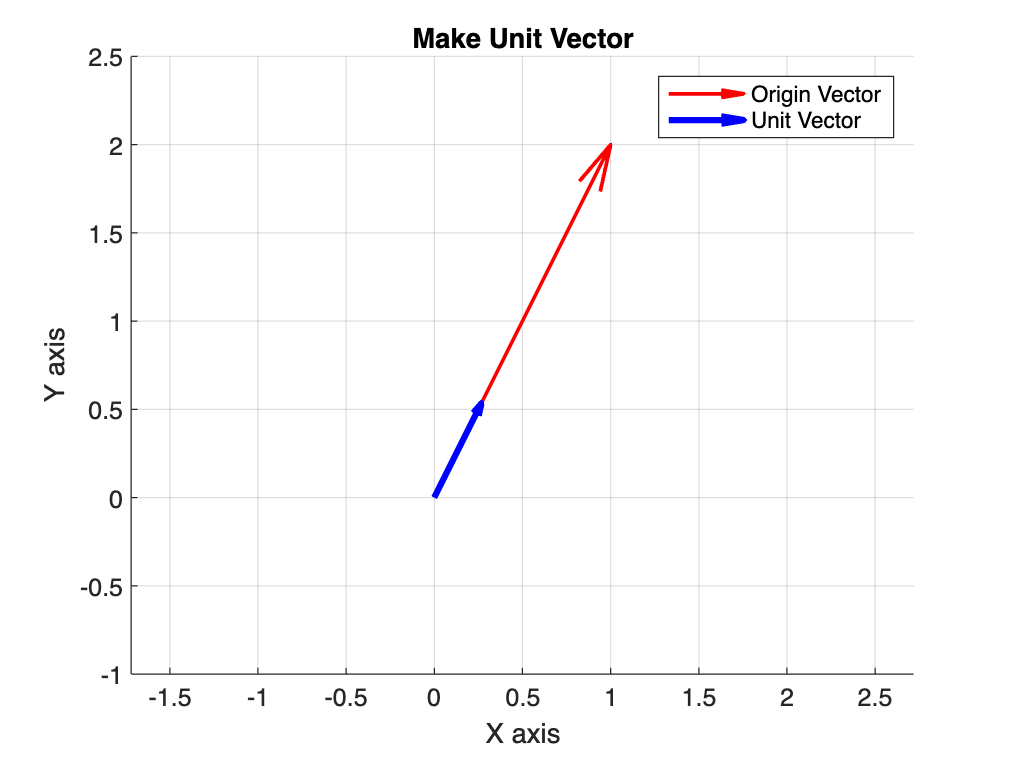


figure;
hold on;

quiver(0, 0, v(1), v(2), 0, 'r', LineWidth=1.5, MaxHeadSize=0.4, DisplayName='Origin Vector');
quiver(0, 0, u_v(1), u_v(2), 0, 'b', LineWidth=2.5, MaxHeadSize=0.4, DisplayName='Unit Vector');
hold off

legend('show');
grid on;

xlabel('X axis');
%xlim([-1, 4]);
xlim([-1, v(1)+0.5]);
ylabel('Y axis');
%ylim([-1, 4]);
ylim([-1, v(2)+0.5]);
title('Make Unit Vector');
axis equal;

## Exercise 3.

### Write the for loop that transposes row vector to column vector without using builtin fuction (e.g., A.T).

clc;
clear;

%r_v = linspace(1, 10, 5);  % generate row vector
r_v = input('Enter a vector [a b c]: ');

% u_v = [];
% for i = 1:size(r_v, 2)
%     u_v = [u_v ; r_v(i)];
% end


function cv = columnVec(v)
    n = size(v, 2);
    cv = zeros(n,1);
    for i = 1:n
        cv(i) = v(i);
    end   
end


r_v

r_v =      1     2     3
     2     3     4


c_v = columnVec(r_v);
c_v

c_v =      1
     2
     2
